clearvars
addpath("kwave/");
addpath("ISM/");

### Parameter Initialisation

% -------------------------
% --------- Grid ----------
dimension = [32,32,32]; % Computational grid x and y dimensions
spacing = 1; % (m) Spacing between each point of the grid
Nt = 1000; % Number of timesteps
dt = 0.001; % (s) Size of timesteps
% -------------------------
% ------ Positions --------
p_source = [0,0,0]; % (x,y,t) Source coordinates
p_receiver = [-8,0,0]; % (x,y,z) Receiver coordinates
% -------------------------
% ---- Wave Equation ------
c = 343; % (m/s) Speed of sound
frequency = 150; % Signal frequency in Hz
k_alpha = [0.1,0.1,0.1]; % Kwave only allows 1 alpha coef per dimension (x,y,z)
alpha = [0.2 0.2 0.2 0.2 0.2 0.2]; % Absorption coefficient
U0 = 0.001; % Radial velocity
a = 1; % Radius of emitting sphere
Q = 4*pi*a^2*U0; % Source strength
rho = 1.125; % Density of air
% -------------------------

### Kwave

[t_array,scale,prefix,in_p,kwave_out_p] = monopole_sound_source(p_source,p_receiver,frequency,dimension,spacing,Nt,dt,k_alpha);

Running k-Wave simulation...
  start time: 17-Nov-2021 08:40:48
  reference sound speed: 343m/s
  dt: 1ms, t_end: 999ms, time steps: 1000
  input grid size: 32 by 32 by 32 grid points (32 by 32 by 32m)
  maximum supported frequency: 171.5Hz
  precomputation completed in 0.16602s
  starting time loop...
  estimated simulation time 5.0685s...
  simulation completed in 4.9098s
  total computation time 5.0823s


### Image Source Method

order = 30;
[~, ism_out_p] = image_source_pressure_wave(p_source,p_receiver,dimension,t_array,spacing,c,frequency,Q,rho,order,alpha,0);

### Plotting

figure;
% -------- Input pressure ---------
subplot(3, 1, 1);

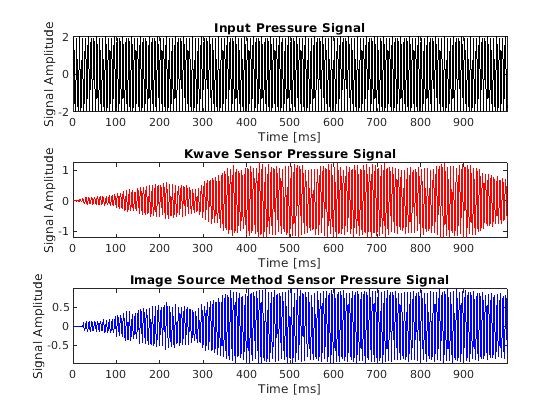

plot(t_array * scale, in_p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Input Pressure Signal');
% ------------ Kwave ---------------
subplot(3, 1, 2);
plot(t_array * scale, kwave_out_p, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Kwave Sensor Pressure Signal');
% ------ Image Source Method -------
subplot(3, 1, 3);
plot(t_array * scale, ism_out_p, 'b-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Image Source Method Sensor Pressure Signal');

### Difference between kwave and image source implementation

diff = abs(ism_out_p - kwave_out_p);

Unrecognized function or variable 'ism_out_p'.

figure;
mean(diff)
plot(t_array,diff);

